# Webinar Text Analytics Toolbox (Oct/2019)

Apresentado por:

Alberto Y Shimahara

## ** Inferência de Tópicos com Latent Dirichlet Allocation (LDA)**

Desenvolvido por:

    - Daniel Vieira

Editado por: 

- Alberto Y Shimahara (oct/2019)

Para esta demo, requer:

- MATLAB R2019b

- Deep Learning Toolbox

- Statistics & Machine Learning Toolbox

- Text Analytics Toolbox

- Parallel Computing Toolbox

% fecha todas as janelas e limpa o workspace do MATLAB e o Command Window
close all
clear all
clc

#### carregando dados da Reuters

*Fonte Reuters **dataset**: *[*https://martin-thoma.com/nlp-reuters/*](https://martin-thoma.com/nlp-reuters/)

*Características:*

•*Notícias de economia e mercado financeiro*

•*10788 textos*

•*90 classes não balanceadas*

•*Cada texto pode ter várias classes (a maioria tem 1 ou 2 classes, mas pode ter até 15)*

•*Número médio de palavras por texto agrupados por classe: de 93 a 1263*

•*Vários **Labels**(assuntos) fortemente correlacionados*

•*Este **dataset** é muito usado para benchmarking de modelos de NLP (Natural **Language**Processing**)*

load('reutersData.mat') % dados já pré processado
data(cellfun(@(x) isempty(x),data.T),:)=[];
data(cellfun(@(x) any(x=="earn",2),data.topics),:)=[];


Um documento tokenizado é um documento representado como uma coleção de palavras (também conhecida como tokens) usada para análise de texto.

txt=tokenizedDocument(data.T);
txt=erasePunctuation(txt); % elimina as pontuações nos textos
txt=removeLongWords(txt,20);% remove palavras maiores que 20 caracteres
txt=removeShortWords(txt,4); % remove palavras curtas com até 4 caracteres
txt=removeStopWords(txt); % Palavras como: "a", "and", "to", and "the" (conhecidads como "stop words") que causam ruido nos dados

Um modelo Bag-of- ngrams registra o número de vezes que cada "n-grama" aparece em cada documento de uma coleção. Um "n-grama" é uma coleção de n palavras sucessivas.

B=bagOfNgrams(txt,'NgramLengths',1); 
B=removeInfrequentNgrams(B,50);%remove n-grams com tamanhos especificados
[~,ind]=maxk(sum(B.Counts~=0,1),25,2); % localiza o maior elemnto do vetor
frequentNgrams=B.Ngrams(ind,:);
B=removeNgrams(B,frequentNgrams); %remove o n-gram especificado do modelo Bag-of_words
B=removeEmptyDocuments(B); % remove documentos que não possuam palavras

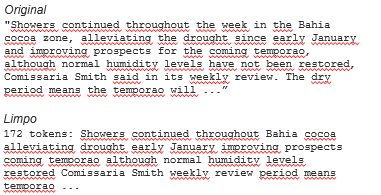

#### Latent Dirichlet allocation (LDA)

O Modelo Latent Dirichlet allocation (LDA) é um algoritmo que descobre topicos em uma coleção de documentos que infere as probabilidades de palavras nos topicos

numTopics = 40;
mdl = fitlda(B,numTopics,'Verbose',1,'Solver','savb','FitTopicConcentration',true,'DataPassLimit',10);

| Minibatch  |  Time per  |  Relative  | Minibatch  |     Topic     |     Topic     |
|            | minibatch  | change in  | perplexity | concentration | concentration |
|            | (seconds)  |   log(L)   |            |               |   iterations  |
|          0 |       0.06 |            |  2.092e+03 |        10.000 |             0 |
|          1 |       0.23 | 5.3302e-02 |  1.421e+03 |        10.000 |             0 |
|          2 |       0.25 | 4.4496e-03 |  1.376e+03 |        10.000 |             0 |
|          3 |       0.21 | 2.6689e-03 |  1.350e+03 |        10.000 |             0 |
|          4 |       0.22 | 8.4124e-04 |  1.341e+03 |        10.000 |             0 |
|          5 |       0.22 | 4.1752e-03 |  1.302e+03 |        10.000 |             0 |
|          6 |       0.22 | 6.4774e-03 |  1.243e+03 | 

p=mdl.FitInfo.Perplexity

p = 568.1723

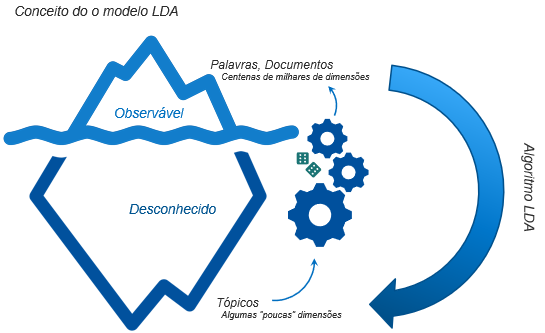

*Efetiva a Probabilidade inferida de cada documento pertencer a cada tópico*

close all
[~,topicInd]=max(mdl.DocumentTopicProbabilities,[],2);
[g,gID]=findgroups(topicInd);% localiza os grupos e retorna quantidade
S=splitapply(@numel,topicInd,g);% divide os dados em grupos e aplica função


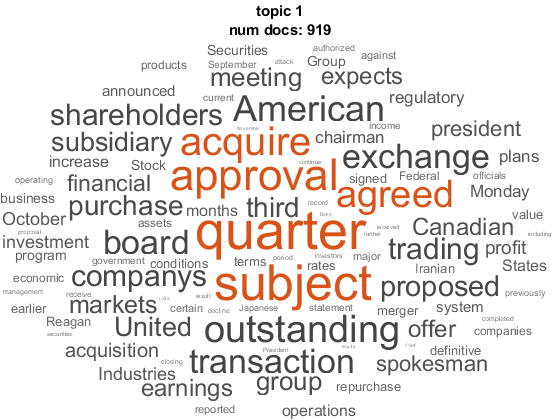

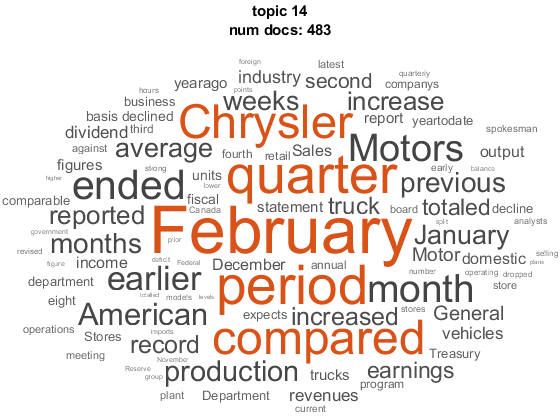

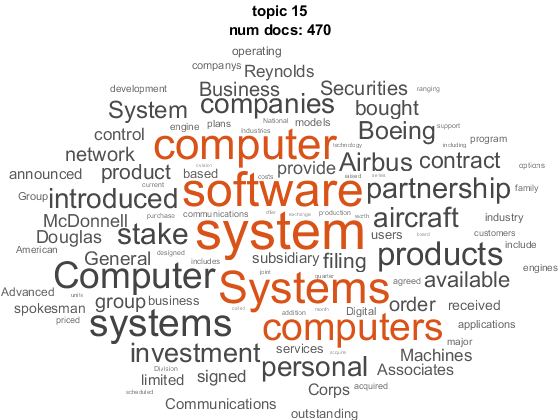

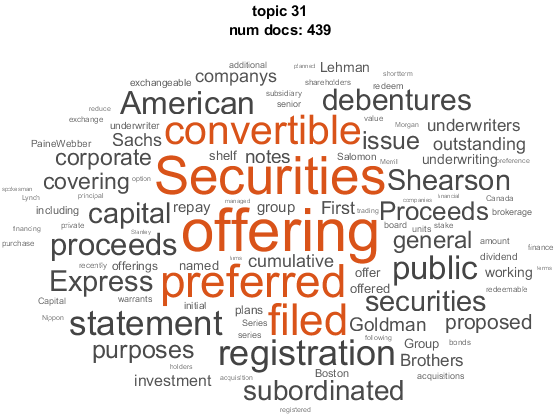

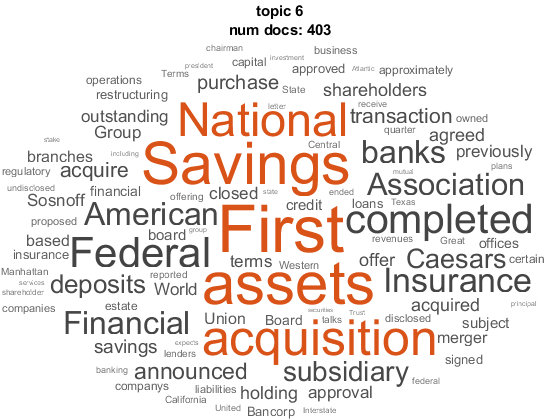

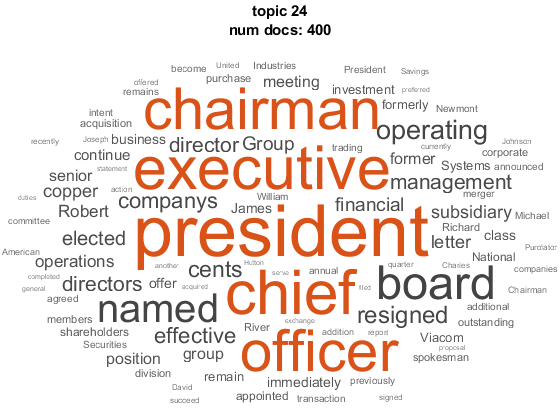

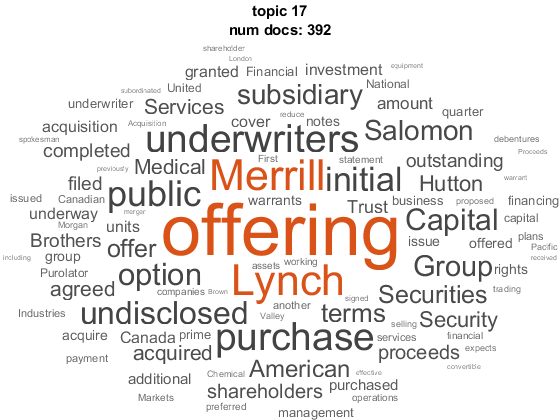

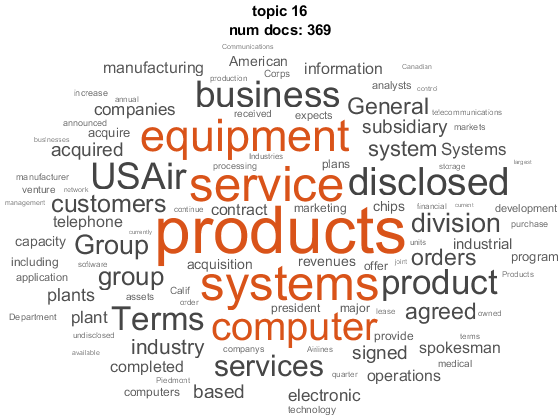

[maxS,sInd]=maxk(S,20);
for k=gID(sInd)'
    subB=removeDocument(B,find(topicInd~=k)); % remove palavras que apareceram menos 
    figure, wordcloud(subB); % Cria uma nuvem de palavras a partir dos dados de texto
    title(["topic "+k,"num docs: "+S(k)])
end